clear
addpath("..\data\geojsonR01\")

txt = readlines("N02-19_RailroadSection.geojson");
% txt = txt(4:end-3);
txt = strrep(txt,'鉄道区分','railsegments');
txt = strrep(txt,'事業者種別','companysegments');
txt = strrep(txt,'路線名','railname');
txt = strrep(txt,'運営会社','company');
geojson = jsondecode(strjoin(txt))

geojson = フィールドをもつ struct :
        type: 'FeatureCollection'
    features: [22016×1 struct]


%新幹線
figure;
gx = geoaxes;
hold(gx)

現在のプロットをホールドしました


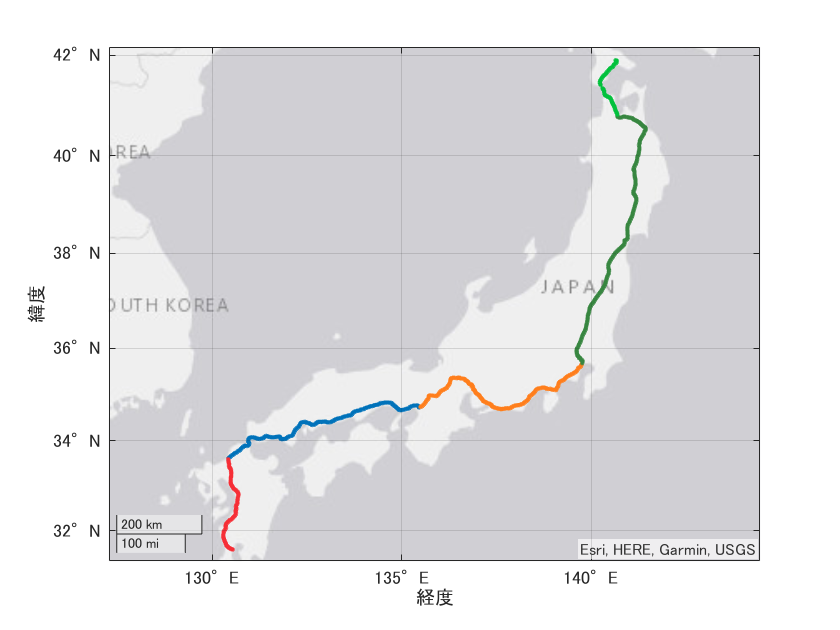

railname = ["山陽新幹線","東海道新幹線","東北新幹線","北海道新幹線","九州新幹線"];
company = ["西日本旅客鉄道","東海旅客鉄道","東日本旅客鉄道","北海道旅客鉄道","九州旅客鉄道"];
color = ["#0072BA","#FF7E1C","#378640","#03C13D","#F62E36"];

for ii=1:length(railname)
    plotCoordinate(gx,geojson,railname(ii),company(ii),color(ii))
end

hold off

%大阪
figure;
gx = geoaxes;
hold(gx)

現在のプロットをホールドしました


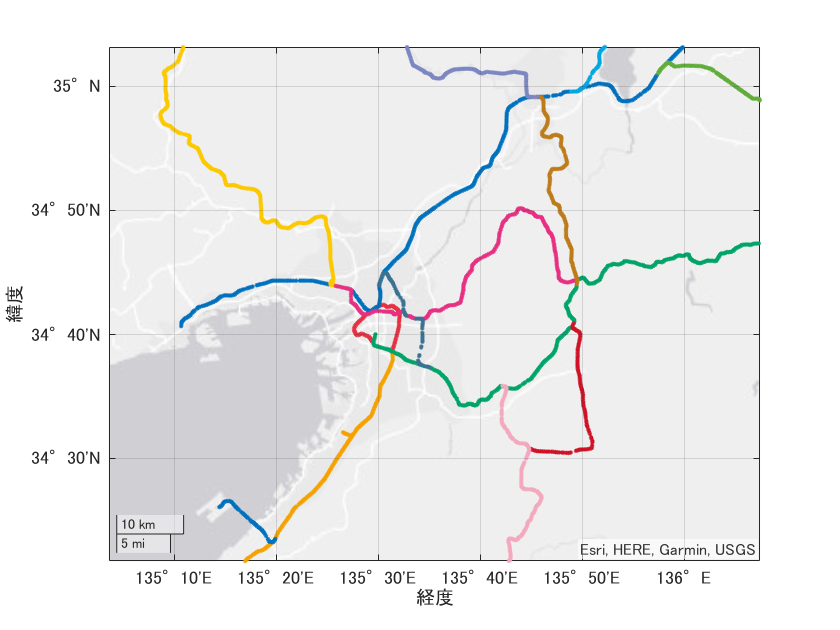


railname = ["大阪環状線","東海道線","湖西線","福知山線","阪和線","関西線","JR東西線","片町線","関西空港線","おおさか東線","奈良線","山陰線","桜井線","和歌山線","草津線"];
color = ["#e73042","#0071be","#00a7e3","#fcc800","#f5a200","#00a469","#e73082","#e73082","#0071be","#3b7293","#bd7b19","#7c86c1","#cf1225","#f3a8be","#60ad3b"];

for ii=1:length(railname)
    plotCoordinate(gx,geojson,railname(ii),"西日本旅客鉄道",color(ii))
end

geolimits([34.362 35.052],[135.060 136.124])

%大阪地下鉄
figure;
gx = geoaxes;
hold(gx)

現在のプロットをホールドしました


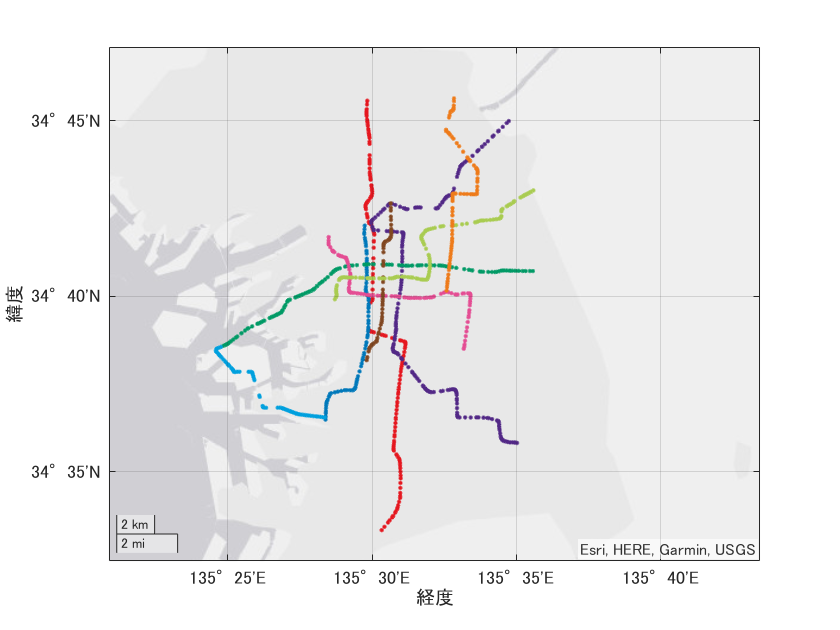


railname = ["1号線(御堂筋線)","2号線(谷町線)","3号線(四つ橋線)","4号線(中央線)","5号線(千日前線)","6号線(堺筋線)","7号線(長堀鶴見緑地線)","8号線（今里筋線）","南港ポートタウン線"];
color = ["#e5171f","#522886","#0078ba","#019a66","#e44d93","#814721","#a9cc51","#ee7b1a","#00a0de"];

for ii=1:length(railname)
    plotCoordinate(gx,geojson,railname(ii),"大阪市高速電気軌道",color(ii))
end

geolimits([34.541 34.785],[135.348 135.724])

function plotCoordinate(gx,geojson,railName,company,color)
    railcoordinate = [];
        for ii=1:length(geojson.features)
        if string(geojson.features(ii).properties.railname)==railName && string(geojson.features(ii).properties.company)==company
            railcoordinate = [railcoordinate;geojson.features(ii).geometry.coordinates];
        end
        end
        railcoordinate = sortrows(railcoordinate);
        geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),'.',"Color",color);
end